# MATLAB Instruction - Far-field evaluation

## Petar V. Peshev

# **Initialization (Spectral Methods Library and Light Speed)**

close all;
clear;
clc;

if ~exist([pwd() '\figures'], 'dir')
    mkdir('figures');
end

addpath('../spectral-methods-library');
c = physconst('LightSpeed');

# **Farfield evaluated using SGF**

## **Theory**

The far field radiated by an electric current can be evaluated asmptotically in spectral domain as follows:

where $\left(x^{\prime } ,y^{\prime } ,z^{\prime } \right)$is the source position while $\left(x,y,z\right)$ is the observation position, $k_{\textrm{xs}} =k\sin \theta \;\cos \phi ,k_{\textrm{ys}} =k\sin \theta \;\sin \phi ,k_{\textrm{zs}} =k\cos \theta \;$rerepresent the dominant plane wave,$\vec{J} \left(k_{\textrm{xs}} ,k_{\textrm{ys}} \right)$ is the FT of the current distribution, and ${\tilde{G} }^{\textrm{ej}}$ is the dyadic SGF for electric currents:

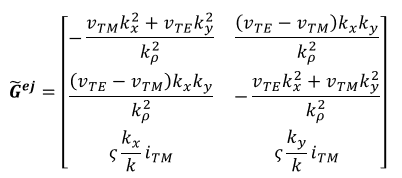

where $v_{\textrm{TM}} ,v_{\textrm{TE}} ,i_{\textrm{TM}} ,i_{\textrm{TE}}$ are obtained from the transmission line solution of the stratification.

**Directivity**

The directivity of a farfield can be obtained as:

where $U\left(\theta ,\phi \right)$ is the radiation intensity:

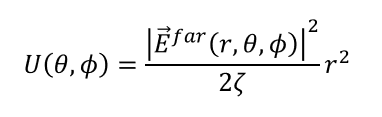

and $P_{\textrm{rad}}$ is the total radiated power:

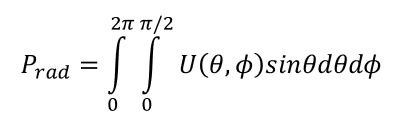

Note that here we only consider the power integrated over the upper hemisphere. For antennas with symmetric patterns such as a free-space dipole, we can simply x2 outside the function. 

## MATLAB Implementation

To evaluate the farfield radiated by a current, we should follow the listed steps:

**(1)** Solve the transmission line model of the straitification. **(2)** Calculate the dyadic SGF. **(3)** Obtain the FT of the current distribution. **(4)** Use Eq.1 to calculate the farfield. **(5) **Evaluate the directivity and radiated power from the farfield.

The above steps are applicable for any source so it would be convenient to build separate routines for these steps, and then reuse them for different applications. Today you should learn how to build these routines for different stratifications:

**(1)** [v_TM, v_TE, i_TM, i_TE] = **txline_xxxx**(k0, er, h, kro, z);

**(2) **ej_SGF = **EJ_SGF**(er, k, kx, ky, v_TM, v_TE, i_TM, i_TE);

**(3)** Jx = **FTCurrent**(k, er, kx, ky, l, w)

**(4)** [Eth, Eph] = **farfield**(k, R_FF, TH, PH, kz, Gxx, Gyx, Gzx, Jx)

**(5)** [Dir, Prad] = **Directivity**(E_tot, Theta, dth, dph, er, r)

# Q1 (3 points): Grounded Dielectric Slab

Evaluate the far field radiated by an electric dipole with $L=W=0\ldotp 25$ mm placed on the top of a grounded slab with thickness $h=0\ldotp 8$ mm and $\varepsilon_r =12$.

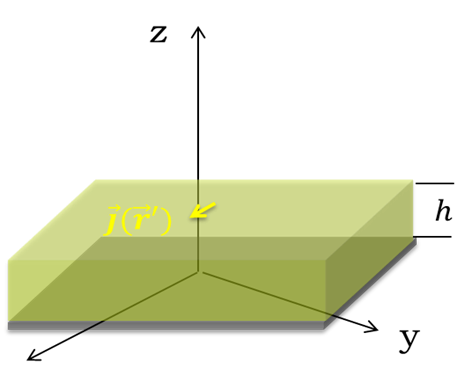

### 1. Far field along the main planes at 28 GHz

Calculate the far field in $\phi =0^{\circ \;} /{90}^{\circ \;}$ planes by considering the radiation in spectral domain.

**Step 1:  Solution of the equivalent transmission line**

The stratification can be modelled as a transmission line, where the current generator represents the electric current:

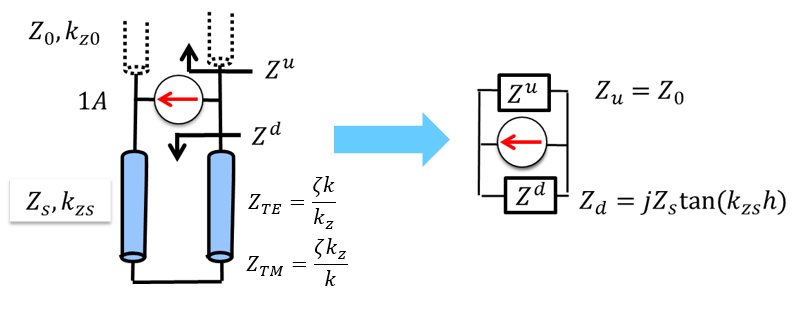

After solving the circuit, one can obtain the voltage and current solutions in the air:

Write a routine to calculate TE/TM solutions: [vtm, vte, itm, ite] = **txline_groundslab**(k0, er, h, krho, z)

% Constant
L  = 0.25e-3;
W  = 0.25e-3;
h  = 0.8e-3;
er = 12;
f  = 28e9;
lambda = 3e8 / f;
k0 = 2 * pi / lambda;

% FF parameters
R_FF = 1;
phi  = (eps:2:360) * pi / 180;
theta = linspace(eps, 90 - 0.1, 90) * pi / 180;
[TH, PH] = meshgrid(theta, phi);
Z    = R_FF * cos(TH);

KX   = k0 * sin(TH) .* cos(PH);
KY   = k0 * sin(TH) .* sin(PH);
KZ   = k0 * cos(TH);
KRHO = sqrt(KX.^2 + KY.^2);

% calculate voltages and currents
[vte, ite, vtm, itm] = stratified_media(k0, KRHO, Z, 'GroundSlab', h, er);

**Step 2:  Calculate the Dyadic SGF**

Build the Dyad for electric current ${\tilde{G} }^{\textrm{ej}}$: ej_SGF = **EJ_SGF**(er, k, kx, ky, v_TM, v_TE, i_TM, i_TE, flag);

% calculate Green's function
SGF = spectral_gf(1, k0, KX, KY, vtm, vte, itm, ite, 'E', 'J');

**Step 3:  Calculate the FT of the current distribution**

For dipole antennas, we can approximate the spatial current distribution using the current distribution along an open circuited transmission line. This distribution can be expressed in general as follows:

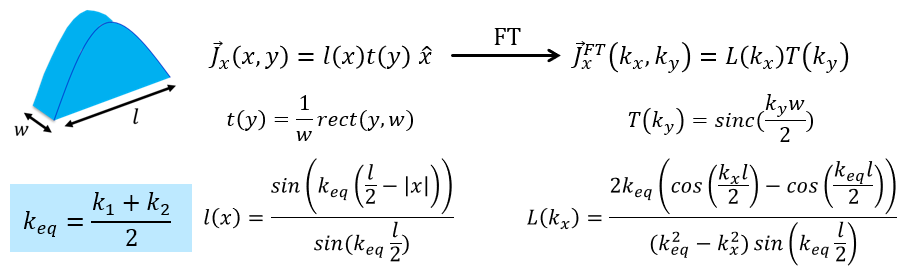

Write a routine to calculate the FT of currents: Jx = **FTCurrent**(k, er, kx, ky, l, w, flag_current)

% calculate FT of current distribution
k_comp = NaN( [size(KX, 1, 2), 3] );
k_comp(:, :, 1) = KX;
k_comp(:, :, 2) = KY;
k_comp(:, :, 3) = KZ;
Jft = ft_current(k0, k_comp, W, L, er, 'dipole', 'x');

**Step 4:  Evaluate far fields **

 

Calculate the FF in Eth and Eph and plot the total field: 

[Eth, Eph] = **farfield**(k, R_FF, TH, PH, kz, Gxx, Gyx, Gzx, Jx);

% calculate far field
sph_grid = NaN( [size(TH, 1, 2), 2] );
sph_grid(:, :, 1) = TH;
sph_grid(:, :, 2) = PH;
E = farfield(k0, R_FF, sph_grid, KZ, Z, SGF, Jft, h);
E_tot = total_field(E);

**Step 5: Directivity**

[dir, ~, power] = directivity(1, E, sph_grid, R_FF);
fprintf('Broadside directivity: %.2f\n', dir(1, 1));

Broadside directivity: 3.07


fprintf('Power: %.2f mW\n', power * 1e3);

Power: 101.95 mW


**Step 6: Plot far field**

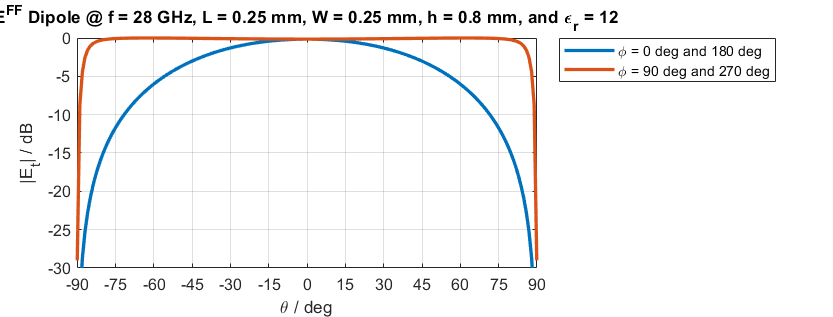

E_tot_norm = norm_magnitude(E_tot, 'dB');
% Plot at 180 deg azimuth planes, from - 90 deg to 90 deg
theta_plot = NaN(1, length(theta) * 2);
theta_plot(1 : length(theta)) = - fliplr(theta) * 180 / pi;
theta_plot(length(theta) + 1 : end) = theta * 180 / pi;
% Plot at 0 to 180 deg azimuth plane
phi0_plot = NaN(1, length(theta) * 2);
phi0_plot(1 : length(theta)) = fliplr(E_tot_norm(91, :));
phi0_plot(length(theta) + 1 : end) = E_tot_norm(1, :);
% Plot at 90 to 270 deg azimuth plane
phi90_plot = NaN(1, length(theta) * 2);
phi90_plot(1 : length(theta)) = fliplr(E_tot_norm(136, :));
phi90_plot(length(theta) + 1 : end) = E_tot_norm(46, :);
% Plot
figure('Position', [250 250 1050 400]);
plot(theta_plot, phi0_plot, 'LineWidth', 2.0, ...
    'DisplayName', '\phi = 0 deg and 180 deg');
hold on;
plot(theta_plot, phi90_plot, 'LineWidth', 2.0, ...
    'DisplayName', '\phi = 90 deg and 270 deg');
grid on;
xticks(-90 : 15 : 90);
xlim([-90 90]);
ylim([-30 0]);
legend show;
legend('location', 'bestoutside');
xlabel('\theta / deg');
ylabel('|E_{t}| / dB');
title(['E^{FF} Dipole @ f = ' num2str(f * 1e-9) ' GHz, L = ' ...
    num2str(L * 1e3) ' mm, W = ' num2str(W * 1e3) ' mm, h = ' ...
    num2str(h * 1e3) ' mm, and \epsilon_{r} = ' num2str(er)]);

% Save figure
saveas(gcf, 'figures\E_field_grounded_dielectric.fig');

The dipole far-field radiation pattern in free space has a doughnut shape, with a minimum radiation parallel to its orientation. Therefore, in free space at $\phi=0^{\circ}\:\text{and}\:180^{\circ}$, the radiation pattern has null radiation at $\theta=90^{\circ}$ (for x-oriented dipole); while at $\phi=90^{\circ}\:\text{and}\:270^{\circ}$, the radiation pattern is constant. However, for a dipole on a dielectric, the $\phi = 90^{\circ}\: \text{ and } \:270^{\circ}$ plane radiation pattern decreases at $\theta=90^{\circ}$, because of the free-space dielectric interface, therefore, the radiation pattern is no longer constant over this plane. On the other hand, at the $\phi=0^{\circ}\:\text{and}\:180^{\circ}$ plane, the radiation pattern is similar to the one of dipole in free space.

### 2. Plot the radiated power from 10 GHz to 40 GHz normalized to the radiated power that the same dipole will radiate in free space.

Calculate the FF as a function of frequency for both stratified and free-space cases. Radiated power can be obtained by integrating the FF pattern: [Dir, Prad] = **Directivity**(E_tot, Theta, dth, dph, er, r);

Dipole in free space: 2*, outside the function.

Dipole in grounded slab:, radiation exists only on the upper hemisphere.

**Step 1: Radiated power by dipole on dielectric normalized to power of dipole in free space**

f = linspace(10, 40, 100) * 1e9;
lambda = 3e8 ./ f;
k0 = 2 * pi ./ lambda;

norm_power = NaN(1, length(f));
for idx = 1 : 1 : length(f)
    KX   = k0(idx) * sin(TH) .* cos(PH);
    KY   = k0(idx) * sin(TH) .* sin(PH);
    KZ   = k0(idx) * cos(TH);
    KRHO = sqrt(KX.^2 + KY.^2);

    k_comp = NaN( [size(KX, 1, 2), 3] );
    k_comp(:, :, 1) = KX;
    k_comp(:, :, 2) = KY;
    k_comp(:, :, 3) = KZ;
    
    % Radiated power by dipole in free space
    [fs_vte, fs_ite, fs_vtm, fs_itm] = tx_fs(k0(idx), KRHO, Z, h);
    FS_SGF = spectral_gf(1, k0(idx), KX, KY, fs_vtm, fs_vte, fs_itm, fs_ite, 'E', 'J');
    FS_Jft = ft_current(k0(idx), k_comp, W, L, 1, 'dipole', 'x');
    FS_E = farfield(k0(idx), R_FF, sph_grid, KZ, Z, FS_SGF, FS_Jft, h);
    % Power radiated in free space
    [~, ~, fs_power] = directivity(1, FS_E, sph_grid, R_FF);
    fs_power = 2 * fs_power;

    % Radiated power by dipole on dielectric
    [vte, ite, vtm, itm] = stratified_media(k0(idx), KRHO, Z, 'GroundSlab', h, er);
    SGF = spectral_gf(1, k0(idx), KX, KY, vtm, vte, itm, ite, 'E', 'J');
    Jft = ft_current(k0(idx), k_comp, W, L, er, 'dipole', 'x');
    E = farfield(k0(idx), R_FF, sph_grid, KZ, Z, SGF, Jft, h);
    % Power radiated
    [~, ~, power] = directivity(1, E, sph_grid, R_FF);

    % Normalized power
    norm_power(idx) = power / fs_power;
end

**Step 2: Plot normalized power**

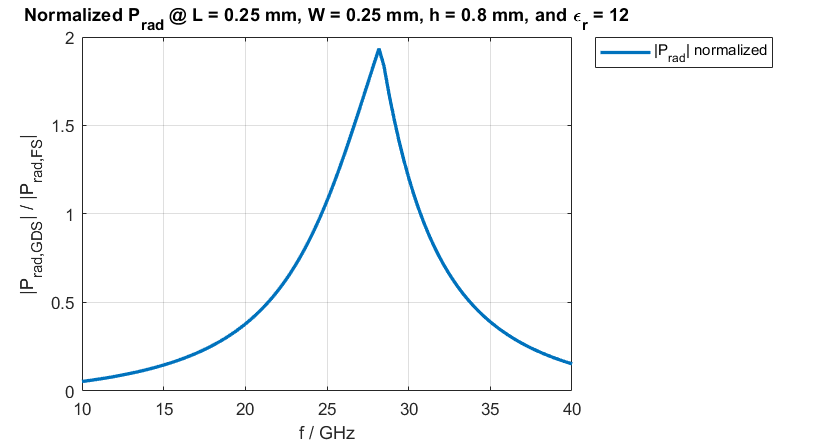

figure('Position', [250 250 750 400]);
plot(f * 1e-9, (norm_power), 'LineWidth', 2.0, 'DisplayName', '|P_{rad}| normalized');
grid on;
xlim([min(f * 1e-9) max(f * 1e-9)]);
legend show;
legend('location', 'bestoutside');
xlabel('f / GHz');
ylabel('|P_{rad,GDS}| / |P_{rad,FS}|');
title(['Normalized P_{rad} @ L = ' num2str(L * 1e3) ' mm, W = ' num2str(W * 1e3) ' mm, ' ...
    'h = ' num2str(h * 1e3) ' mm, and \epsilon_{r} = ' num2str(er)]);

saveas(gcf, 'figures\normalized_Prad.fig');

The normalized radiated power increases until it reaches the peak at a certain frequency related to the dielectric length h, and then decreases; this pattern repeats. The radiated power is maximum at frequencies for which the radiated field towards the dielectric is reflected and in phase to the radiated power above the dielectric.

### 3. For which thickness is this normalized power of the dipole the highest? Why?

Find this value in **2**, and represent it in terms of wavelength in dielectric.

h_opt = h / lambda(find(norm_power == max(norm_power), 1));
fprintf('Optimal h in terms of wavelength: %.3f / wavelength\n', h_opt);

Optimal h in terms of wavelength: 0.075 / wavelength


As previously mentioned, the normalized power is maximum at the wavelength for which the reflected power from the ground plane (radiated towards the dielectric) is in-phase with the power radiated towards the free space.

# Q2 (4 points): Standard Leaky-wave antenna

Calculate the far field radiated by a magnetic current in the presence of the stratification shown in the figure. Consider $h=5\ldotp 4$mm, $h_s =0\ldotp 77$mm, $\varepsilon_r =12$, and a half-wavelength magnetic dipole with $W=\lambda /20$.

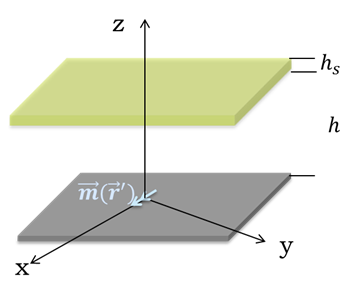

### 1. Far field along main planes at 26**, 28**, and 30 GHz.

Calculate the far field in $\phi =0^{\circ \;} /{90}^{\circ \;}$ planes at **three** frequency points.

**Step 1:  Solution of the equivalent transmission line**

 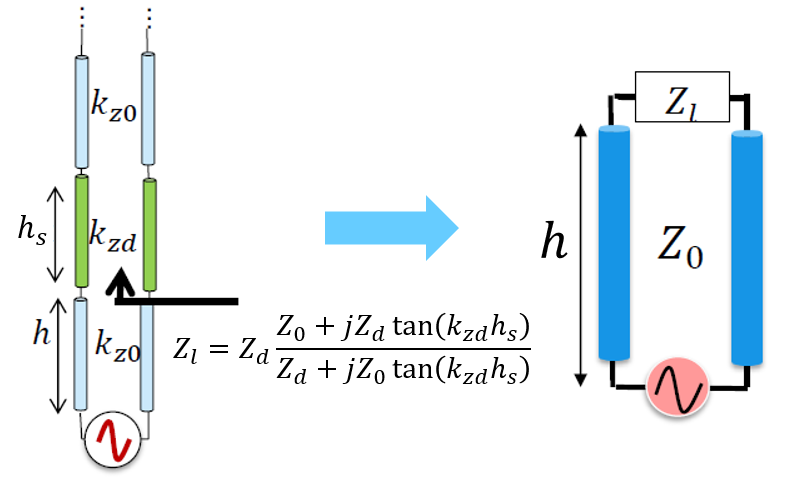

Write a routine to calculate TE/TM solutions: [vtm, vte, itm, ite] = **txline_superstrate**(k0, er, h, hs, krho, z)

**Step 2:  Calculate the Dyadic SGF**

Build the Dyad for magnetic current ${\tilde{G} }^{\textrm{em}}$: em_SGF = **EM_SGF**(er, k, kx, ky, v_TM, v_TE, i_TM, i_TE, flag);

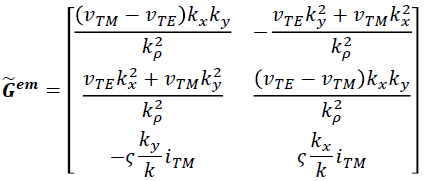

**Step 3:  Calculate the FT of the current distribution**

Same routine as the previous case.

**Step 4:  Evaluate far fields **

Same routine as the previous case. In fact, you can find $h=\frac{\lambda_{0\;} }{2}$, $h_s =\frac{\lambda_0 }{4\sqrt{\;\varepsilon_r }}$ are the resonant conditions.

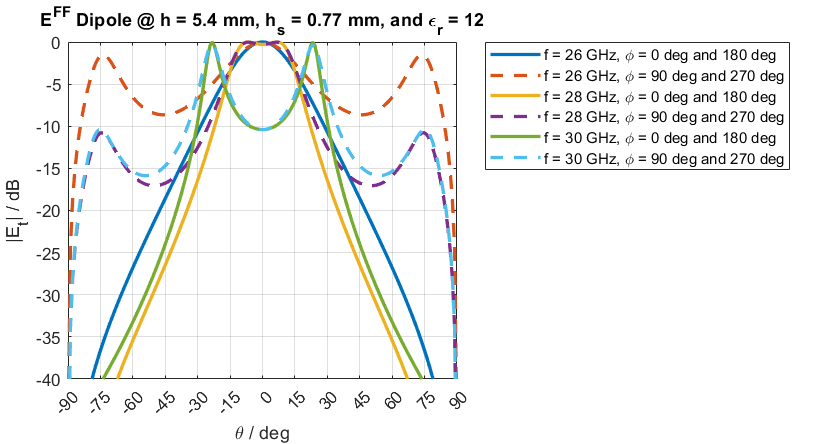

clear;

% Parameters
h  = 5.4e-3;
hs = 0.77e-3;
er = 12;
f  = [26 28 30] * 1e9;

% Dependent parameters
lambda = 3e8 ./ f;
L  = lambda / 2;
W  = lambda / 20;
k0 = 2 * pi ./ lambda;

% Spherical grid parameters
phi      = (eps:2:360) * pi / 180;
theta    = linspace(eps, 90 - 0.1, 90) * pi / 180;
[TH, PH] = meshgrid(theta, phi);

sph_grid = NaN( [size(TH, 1, 2), 2] );
sph_grid(:, :, 1) = TH;
sph_grid(:, :, 2) = PH;

% FF parameters
R_FF = 1;
Z    = R_FF * cos(TH);

E = NaN( [size(sph_grid, 1, 2), 3, length(f)] );
E_tot = NaN( [size(sph_grid, 1, 2), length(f)] );
for idx = 1 : 1 : length(f)
    KX   = k0(idx) * sin(TH) .* cos(PH);
    KY   = k0(idx) * sin(TH) .* sin(PH);
    KZ   = k0(idx) * cos(TH);
    KRHO = sqrt(KX.^2 + KY.^2);

    k_comp = NaN( [size(KX, 1, 2), 3] );
    k_comp(:, :, 1) = KX;
    k_comp(:, :, 2) = KY;
    k_comp(:, :, 3) = KZ;
    
    % calculate voltages and currents
    [vte, ite, vtm, itm] = stratified_media(k0(idx), KRHO, Z, 'Superstrate', h, hs, er);

    % calculate Green's function
    SGF = spectral_gf(1, k0(idx), KX, KY, vtm, vte, itm, ite, 'E', 'M');

    % calculate FT of current distribution
    Mx = ft_current(k0(idx), k_comp, W(idx), L(idx), 1, 'dipole', 'x');
    
    % calculate far field
    E(:, :, :, idx) = farfield(k0(idx), R_FF, sph_grid, KZ, Z, SGF, Mx);
    E_tot(:, :, idx) = total_field(E(:, :, :, idx));
end

% Plot at 180 deg azimuth planes, from - 90 deg to 90 deg
theta_plot = NaN(1, length(theta) * 2);
theta_plot(1 : length(theta)) = - fliplr(theta) * 180 / pi;
theta_plot(length(theta) + 1 : end) = theta * 180 / pi;
figure('Position', [250 250 750 400]);
for idx = 1 : 1 : length(f)
    E_tot_norm = norm_magnitude(E_tot, 'dB');
    % Plot at 0 to 180 deg azimuth plane
    phi0_plot = NaN(1, length(theta) * 2);
    phi0_plot(1 : length(theta)) = fliplr(E_tot_norm(91, :, idx));
    phi0_plot(length(theta) + 1 : end) = E_tot_norm(1, :, idx);
    % Plot at 90 to 270 deg azimuth plane
    phi90_plot = NaN(1, length(theta) * 2);
    phi90_plot(1 : length(theta)) = fliplr(E_tot_norm(136, :, idx));
    phi90_plot(length(theta) + 1 : end) = E_tot_norm(46, :, idx);
    plot(theta_plot, phi0_plot, 'LineWidth', 2.0, 'DisplayName', ...
        ['f = ' num2str(f(idx) * 1e-9) ' GHz, \phi = 0 deg and 180 deg']);
    hold on;
    plot(theta_plot, phi90_plot, '--', 'LineWidth', 2.0, 'DisplayName', ...
        ['f = ' num2str(f(idx) * 1e-9) ' GHz, \phi = 90 deg and 270 deg']);
    hold on;
end
hold off;
grid on;
xticks(-90 : 15 : 90);
xlim([-90 90]);
ylim([-40 0]);
legend show;
legend('location', 'bestoutside');
xlabel('\theta / deg');
ylabel('|E_{t}| / dB');
title(['E^{FF} Dipole @ h = ' num2str(h * 1e3) ' mm, h_{s} = ' ...
    num2str(hs * 1e3) ' mm, and \epsilon_{r} = ' num2str(er)]);

saveas(gcf, 'figures\E_field_superstrate.fig');

For the far-field radiation pattern in the superstrate, the leaky wave peaks (resonance) can be clearly observed at the $\phi=90^{\circ}\:\text{and}\:270^{\circ}$ planes, at around $\theta=75^{\circ}$. At the $\phi=0^{\circ}\:\text{and}\:180^{\circ}$ plane, as the frequency increases the broadside field decreases and resonance occur in this plane as well. Therefore at certain conditions (previously mentioned $h = \lambda_{0}/2$ and $h_{s}=\lambda_{0}/(4\sqrt{\epsilon_{r}})$), resonance can be observed at the $\phi=0^{\circ}\:\text{and}\:180^{\circ}$ plane.

### 2. Compare the far field with that of the magnetic current radiating in free space at 28 GHz.

Solve a new transmission line for free space case.

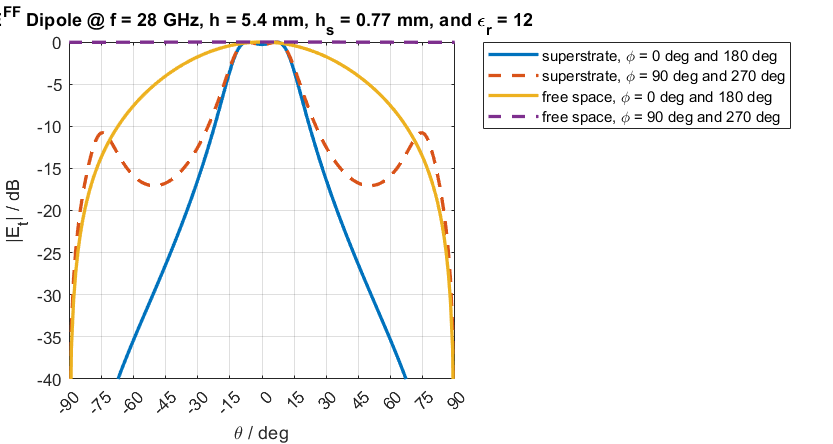

clear;

% Parameters
h  = 5.4e-3;
hs = 0.77e-3;
er = 12;
f  = 28 * 1e9;

% Dependent parameters
lambda = 3e8 / f;
L  = lambda / 2;
W  = lambda / 20;
k0 = 2 * pi / lambda;

% Spherical grid parameters
phi  = (eps:2:360) * pi / 180;
theta = linspace(eps, 90 - 0.1, 90) * pi / 180;
[TH, PH] = meshgrid(theta, phi);

sph_grid = NaN( [size(TH, 1, 2), 2] );
sph_grid(:, :, 1) = TH;
sph_grid(:, :, 2) = PH;

% FF parameters
R_FF = 1;
Z    = R_FF * cos(TH);

% Wave vector components in free space
KX   = k0 * sin(TH) .* cos(PH);
KY   = k0 * sin(TH) .* sin(PH);
KZ   = k0 * cos(TH);
KRHO = sqrt(KX.^2 + KY.^2);

k_comp = NaN( [size(KX, 1, 2), 3] );
k_comp(:, :, 1) = KX;
k_comp(:, :, 2) = KY;
k_comp(:, :, 3) = KZ;
    
% Radiated power by dipole in free space
[fs_vte, fs_ite, fs_vtm, fs_itm] = tx_fs(k0, KRHO, Z, h);
FS_SGF = spectral_gf(1, k0, KX, KY, fs_vtm, fs_vte, fs_itm, fs_ite, 'E', 'J');
FS_Mft = ft_current(k0, k_comp, W, L, 1, 'dipole', 'x');
FS_E = farfield(k0, R_FF, sph_grid, KZ, Z, FS_SGF, FS_Mft, h);
E_fs_tot = total_field(FS_E);

% calculate voltages and currents
[vte, ite, vtm, itm] = stratified_media(k0, KRHO, Z, 'Superstrate', h, hs, er);

% calculate Green's function
SGF = spectral_gf(1, k0, KX, KY, vtm, vte, itm, ite, 'E', 'M');

% calculate FT of current distribution
Mx = ft_current(k0, k_comp, W, L, 1, 'dipole', 'x');

% calculate far field
E = farfield(k0, R_FF, sph_grid, KZ, Z, SGF, Mx);
E_tot = total_field(E);

% Plot at 180 deg azimuth planes, from - 90 deg to 90 deg
theta_plot = NaN(1, length(theta) * 2);
theta_plot(1 : length(theta)) = - fliplr(theta) * 180 / pi;
theta_plot(length(theta) + 1 : end) = theta * 180 / pi;
% Superstrate normalized E far-field in dB
E_tot_norm = norm_magnitude(E_tot, 'dB');
% Plot at 0 to 180 deg azimuth plane
phi0_plot = NaN(1, length(theta) * 2);
phi0_plot(1 : length(theta)) = fliplr(E_tot_norm(91, :));
phi0_plot(length(theta) + 1 : end) = E_tot_norm(1, :);
% Plot at 90 to 270 deg azimuth plane
phi90_plot = NaN(1, length(theta) * 2);
phi90_plot(1 : length(theta)) = fliplr(E_tot_norm(136, :));
phi90_plot(length(theta) + 1 : end) = E_tot_norm(46, :);
% Free space normalized E far-field in dB
E_fs_tot_norm = norm_magnitude(E_fs_tot, 'dB');
% Plot at 0 to 180 deg azimuth plane
phi0_plot_fs = NaN(1, length(theta) * 2);
phi0_plot_fs(1 : length(theta)) = fliplr(E_fs_tot_norm(91, :));
phi0_plot_fs(length(theta) + 1 : end) = E_fs_tot_norm(1, :);
% Plot at 90 to 270 deg azimuth plane
phi90_plot_fs = NaN(1, length(theta) * 2);
phi90_plot_fs(1 : length(theta)) = fliplr(E_fs_tot_norm(136, :));
phi90_plot_fs(length(theta) + 1 : end) = E_fs_tot_norm(46, :);
% Plot
figure('Position', [250 250 750 400]);
plot(theta_plot, phi0_plot, 'LineWidth', 2.0, ...
    'DisplayName', 'superstrate, \phi = 0 deg and 180 deg');
hold on;
plot(theta_plot, phi90_plot, '--', 'LineWidth', 2.0, ...
    'DisplayName', 'superstrate, \phi = 90 deg and 270 deg');
hold on;
plot(theta_plot, phi0_plot_fs, 'LineWidth', 2.0, ...
    'DisplayName', 'free space, \phi = 0 deg and 180 deg');
hold on;
plot(theta_plot, phi90_plot_fs, '--', 'LineWidth', 2.0, ...
    'DisplayName', 'free space, \phi = 90 deg and 270 deg');
grid on;
xticks(-90 : 15 : 90);
xlim([-90 90]);
ylim([-40 0]);
legend show;
legend('location', 'bestoutside');
xlabel('\theta / deg');
ylabel('|E_{t}| / dB');
title(['E^{FF} Dipole @ f = ' num2str(f * 1e-9) ' GHz, h = ' ...
    num2str(h * 1e3) ' mm, h_{s} = ' num2str(hs * 1e3) ...
    ' mm, and \epsilon_{r} = ' num2str(er)]);

saveas(gcf, 'figures\E_field_superstrate_and_free_space.fig');

Compared to the free space radiation pattern, at the $\phi=0^{\circ}\:\text{and}\:180^{\circ}$ plane, superstrate is much more directive, with the electric far-field decreases much faster at larger $\theta$ angles. While at the $\phi=90^{\circ}\:\text{and}\:270^{\circ}$, the electric far-field pattern is not constant as in the free space case, the leaky wave (resonance) peaks are observed at around $\theta=75^{\circ}$, and the field is also much more directive as at the $\phi=0^{\circ}\:\text{and}\:180^{\circ}$ plane.

### 3. Directivity$\left(\textrm{at}\;\theta =0^{\circ \;} \right)$ as a function of relative permittivity at 28 GHz. Consider a variation $\left(\varepsilon_r \right)$ from 1 to 25,  with the dielectric thickness $h_s =\frac{\lambda_0 }{4\sqrt{\;\varepsilon_r }}$. 

Calculate the directivity at $\theta =0^{\circ \;}$ as a function of $\varepsilon_r$. 

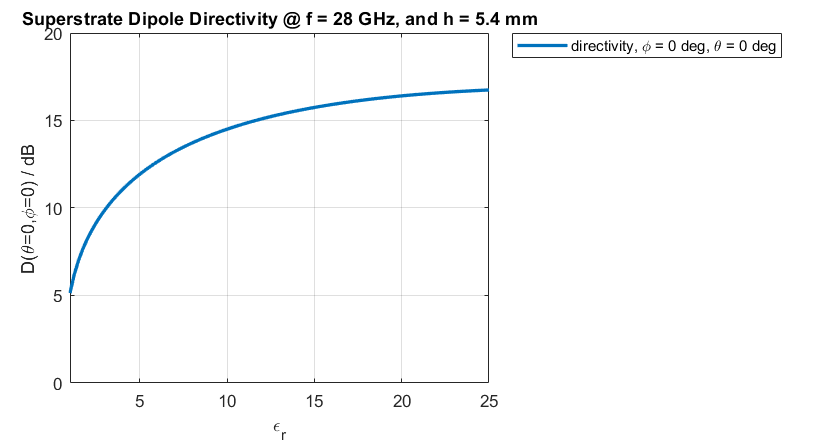

clear;

% Parameters
h  = 5.4e-3;
er = linspace(1, 25, 100);
f  = 28 * 1e9;

% Dependent parameters
lambda = 3e8 / f;
L  = lambda / 2;
W  = lambda / 20;
k0 = 2 * pi / lambda;
hs = lambda ./ (4 * sqrt(er));

% Spherical grid parameters
phi  = (eps:2:360) * pi / 180;
theta = linspace(eps, 90 - 0.1, 90) * pi / 180;
[TH, PH] = meshgrid(theta, phi);

sph_grid = NaN( [size(TH, 1, 2), 2] );
sph_grid(:, :, 1) = TH;
sph_grid(:, :, 2) = PH;

% FF parameters
R_FF = 1;
Z    = R_FF * cos(TH);

% Wave vector components in free space
KX   = k0 * sin(TH) .* cos(PH);
KY   = k0 * sin(TH) .* sin(PH);
KZ   = k0 * cos(TH);
KRHO = sqrt(KX.^2 + KY.^2);

k_comp = NaN( [size(KX, 1, 2), 3] );
k_comp(:, :, 1) = KX;
k_comp(:, :, 2) = KY;
k_comp(:, :, 3) = KZ;

dir = NaN(1, length(er));
for idx = 1 : 1 : length(er)

    % calculate voltages and currents
    [vte, ite, vtm, itm] = stratified_media(k0, KRHO, Z, 'Superstrate', h, hs(idx), er(idx));

    % calculate Green's function
    SGF = spectral_gf(1, k0, KX, KY, vtm, vte, itm, ite, 'E', 'M');

    % calculate FT of current distribution
    Mx = ft_current(k0, k_comp, W, L, 1, 'dipole', 'x');
    
    % calculate far field
    E = farfield(k0, R_FF, sph_grid, KZ, Z, SGF, Mx);

    [dir_all, ~, ~] = directivity(1, E, sph_grid, R_FF);
    dir(idx) = dir_all(1, 1);
end

% Plot
figure('Position', [250 250 750 400]);
plot(er, 10 * log10(dir), 'LineWidth', 2.0, 'DisplayName', 'directivity, \phi = 0 deg, \theta = 0 deg');
grid on;
xlim([min(er) max(er)]);
ylim([0 20]);
legend show;
legend('location', 'bestoutside');
xlabel('\epsilon_{r}');
ylabel('D(\theta=0,\phi=0) / dB');
title(['Superstrate Dipole Directivity @ f = ' num2str(f * 1e-9) ' GHz, and h = ' num2str(h * 1e3) ' mm']);

saveas(gcf, 'figures\directivity_superstrate.fig');

As the relative permittivity of the dielectric increases, the equivalent aperture also increases, making the radiation pattern more directive. At larger dielectric permittivity, the broadside directivity increases more slowly because the aperture starts to increases more slowly (less power is carried by the reflection in the first free space medium at distance close to the aperture limit).

# Q3 (3 points): Resonant Leaky-wave antenna

Calculate the far field radiated by a magnetic current into an infinite medium in the presence of the stratification shown in the figure. Consider $h=5\ldotp 4$ mm,  a frequency of $28$ GHz, and a half-wavelength magnetic dipole with $W=\lambda /20$. 

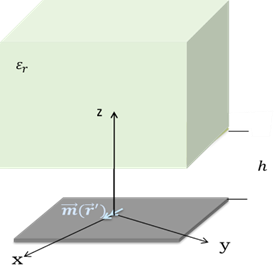

### 1. Far field along main planes when $\varepsilon_r =12$.

Note that the far field is now radiated inside a dielectric medium. The spectral parameters should be modified:


$$k_{\textrm{xs}} =k_d \;\sin \theta \;\cos \phi ,k_{\textrm{ys}} =k_d \;\sin \theta \;\sin \phi ,k_{\textrm{zs}} =k_d \;\cos \theta \;$$


**Step 1:  Solution of the equivalent  transmission line**

clear;

% Parameters
h  = 5.4e-3;
er = 12;
f  = 28 * 1e9;

% Dependent parameters
lambda = 3e8 / f;
L  = lambda / 2;
W  = lambda / 20;
k0 = 2 * pi / lambda;

% Spherical grid parameters
phi  = (eps:2:360) * pi / 180;
theta = linspace(eps, 90 - 0.1, 90) * pi / 180;
[TH, PH] = meshgrid(theta, phi);

sph_grid = NaN( [size(TH, 1, 2), 2] );
sph_grid(:, :, 1) = TH;
sph_grid(:, :, 2) = PH;

% FF parameters
R_FF = 1;
Z    = R_FF * cos(TH);

% Wave vector components in free space
k = k0 * sqrt(er);
KX   = k * sin(TH) .* cos(PH);
KY   = k * sin(TH) .* sin(PH);
KZ   = k * cos(TH);
KRHO = sqrt(KX.^2 + KY.^2);

k_comp = NaN( [size(KX, 1, 2), 2] );
k_comp(:, :, 1) = KX;
k_comp(:, :, 2) = KY;
k_comp(:, :, 3) = KZ;
    
% calculate voltages and currents
[vte, ite, vtm, itm] = stratified_media(k0, KRHO, Z, 'SemiInfiniteSuperstrate', h, er);


**Step 2:  Calculate the Dyadic SGF**

% calculate Green's function
SGF = spectral_gf(er, k, KX, KY, vtm, vte, itm, ite, 'E', 'M');

**Step 3:  Calculate the FT of the current distribution**

% calculate FT of current distribution
Mx = ft_current(k0, k_comp, W, L, 1, 'dipole', 'x');

**Step 4:  Evaluate far fields **

% calculate far field
E = farfield(k, R_FF, sph_grid, KZ, Z, SGF, Mx);
E_tot = total_field(E);

**Step 5: Plot far field**

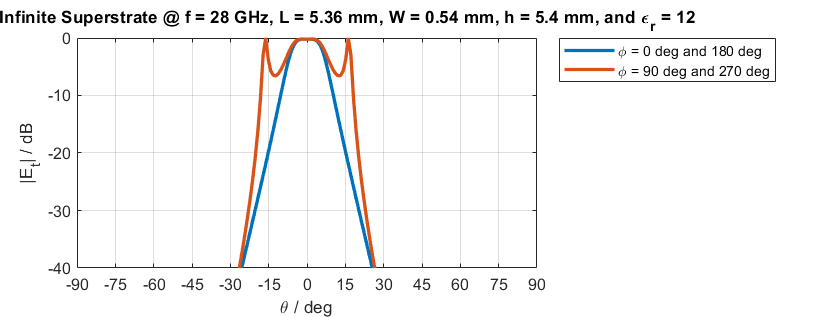

E_tot_norm = norm_magnitude(E_tot, 'dB');
% Plot at 180 deg azimuth planes, from - 90 deg to 90 deg
theta_plot = NaN(1, length(theta) * 2);
theta_plot(1 : length(theta)) = - fliplr(theta) * 180 / pi;
theta_plot(length(theta) + 1 : end) = theta * 180 / pi;
% Plot at 0 to 180 deg azimuth plane
phi0_plot = NaN(1, length(theta) * 2);
phi0_plot(1 : length(theta)) = fliplr(E_tot_norm(91, :));
phi0_plot(length(theta) + 1 : end) = E_tot_norm(1, :);
% Plot at 90 to 270 deg azimuth plane
phi90_plot = NaN(1, length(theta) * 2);
phi90_plot(1 : length(theta)) = fliplr(E_tot_norm(136, :));
phi90_plot(length(theta) + 1 : end) = E_tot_norm(46, :);
% Plot
figure('Position', [250 250 1050 400]);
plot(theta_plot, phi0_plot, 'LineWidth', 2.0, ...
    'DisplayName', '\phi = 0 deg and 180 deg');
hold on;
plot(theta_plot, phi90_plot, 'LineWidth', 2.0, ...
    'DisplayName', '\phi = 90 deg and 270 deg');
grid on;
xticks(-90 : 15 : 90);
xlim([-90 90]);
ylim([-40 0]);
legend show;
legend('location', 'bestoutside');
xlabel('\theta / deg');
ylabel('|E_{t}| / dB');
title(['E^{FF} Semi-Infinite Superstrate @ f = ' num2str(f * 1e-9) ' GHz, L = ' ...
    num2str(round(L * 1e3, 2)) ' mm, W = ' num2str(round(W * 1e3, 2)) ' mm, h = ' num2str(h * 1e3) ...
    ' mm, and \epsilon_{r} = ' num2str(er)]);

saveas(gcf, 'figures\E_field_semi_infinite_superstrate.fig');

The electric far-field at the $\phi=0^{\circ}\:\text{and}\:180^{\circ}$ and $\phi=90^{\circ}\:\text{and}\:270^{\circ}$ for the semi-infinite superstrate are similar to respective far-field in the same planes for the superstrate; however, the radiation pattern of the semi-infnite superstrate is much more directive to the one for the semi-infinite superstrate.

### 2. Directivity$\left(\textrm{at}\;\theta =0^{\circ \;} \right)$ as a function of relative permittivity at 28 GHz. Consider a variation $\left(\varepsilon_r \right)$ from 1 to 25. 

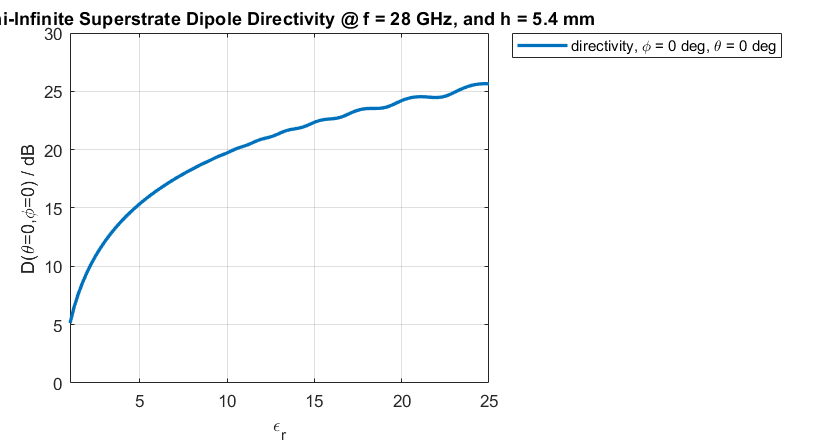

clear;

% Parameters
h  = 5.4e-3;
er = linspace(1, 25, 100);
f  = 28 * 1e9;

% Dependent parameters
lambda = 3e8 / f;
L  = lambda / 2;
W  = lambda / 20;
k0 = 2 * pi / lambda;

% Spherical grid parameters
phi  = (eps:2:360) * pi / 180;
theta = linspace(eps, 90 - 0.1, 90) * pi / 180;
[TH, PH] = meshgrid(theta, phi);

sph_grid = NaN( [size(TH, 1, 2), 2] );
sph_grid(:, :, 1) = TH;
sph_grid(:, :, 2) = PH;

% FF parameters
R_FF = 1;
Z    = R_FF * cos(TH);

dir = NaN(1, length(er));
for idx = 1 : 1 : length(er)
    k = k0 * sqrt(er(idx));
    KX   = k * sin(TH) .* cos(PH);
    KY   = k * sin(TH) .* sin(PH);
    KZ   = k * cos(TH);
    KRHO = sqrt(KX.^2 + KY.^2);

    k_comp = NaN( [size(KX, 1, 2), 2] );
    k_comp(:, :, 1) = KX;
    k_comp(:, :, 2) = KY;
    k_comp(:, :, 3) = KZ;

    % calculate voltages and currents
    [vte, ite, vtm, itm] = stratified_media(k0, KRHO, Z, 'SemiInfiniteSuperstrate', h, er(idx));

    % calculate Green's function
    SGF = spectral_gf(er(idx), k, KX, KY, vtm, vte, itm, ite, 'E', 'M');

    % calculate FT of current distribution
    Mx = ft_current(k0, k_comp, W, L, 1, 'dipole', 'x');
    
    % calculate far field
    E = farfield(k, R_FF, sph_grid, KZ, Z, SGF, Mx);

    [dir_all, ~, ~] = directivity(er(idx), E, sph_grid, R_FF);
    dir(idx) = dir_all(1, 1);
end

% Plot
figure('Position', [250 250 750 400]);
plot(er, 10 * log10(dir), 'LineWidth', 2.0, 'DisplayName', 'directivity, \phi = 0 deg, \theta = 0 deg');
grid on;
xlim([min(er) max(er)]);
ylim([0 30]);
legend show;
legend('location', 'bestoutside');
xlabel('\epsilon_{r}');
ylabel('D(\theta=0,\phi=0) / dB');
title(['Semi-Infinite Superstrate Dipole Directivity @ f = ' num2str(f * 1e-9) ' GHz, and h = ' num2str(h * 1e3) ' mm']);

saveas(gcf, 'figures\directivity_semi_infinite_superstrate.fig');

Similarly as for the superstrate, in the semi-infinite superstrate, the broadside directivity increases as the equivalent relative permittivity of the dielectric increases, as a result of the increasing equivalent aperture with increasing relative permittivity.

### 3. Compare the achieved directivity with that from the previous example.

The directivity of the superstrate and semi-infinite superstrate increase with the increasing relative permittivity of the dielectric, because of the increasing apertucture in both cases. However, the directivity of the semi-infinite superstrate is larger than the directivity of the superstrate, because of the smaller load impedance as seen from the air medium (above the PEC); for superstrate, the load impedance (as seen from the ) is

$Z_{L}=\frac{\zeta_{0}}{\epsilon_{r}}$,

while for semi-infinite superstrate, the load impedance is

$Z_{L}=\frac{\zeta_{0}}{\sqrt{\epsilon_{r}}}$.

Therefore, for the semi-infinite superstrate, the load impedance is closer to the free space medium, resulting in smaller reflection coefficient and more directivity.